clear all; close all; clc;

pixel_observation_x_1 = 10

pixel_observation_x_1 = 10

pixel_observation_y_1 = 20

pixel_observation_y_1 = 20

sample_count = 449

sample_count = 199

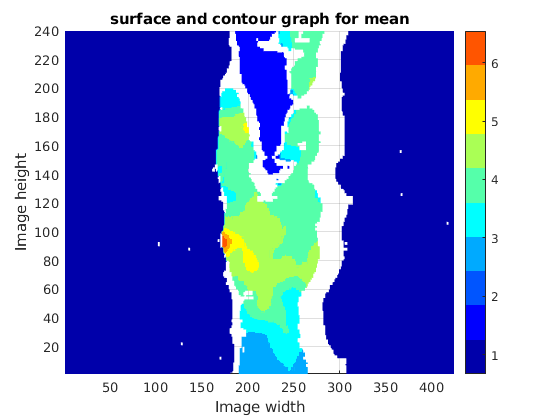

width = 424;
height = 240;
path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/wo_glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

sample_vector_truth_1 = zeros(sample_count,1);

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    matrix_mean = zeros(height,width);
    avg_mean_col = data(:,4);
    
    i=1;
    for cImage_x = 1:height
        for rImage_y = 1:width
            matrix_mean(cImage_x,rImage_y) = avg_mean_col(i);
            
            i = i+ 1;
        end
    end
    v = matrix_mean(pixel_observation_x_1,pixel_observation_y_1);
    
    sample_vector_truth_1(callback_count) = v;
    
    if(callback_count<=2)
        % surfc for the mean
        x = 1:width;
        y = 1:height;
        z = matrix_mean;
        [X1,X2]=meshgrid(x,y);
        surfc(X1,X2,z)
        
        grid on
        view(2)
        title('surface and contour graph for mean')
        xlabel('Image width')
        ylabel('Image height')
        zlabel('mean')
        shading interp
        colormap (jet(10))
        colorbar
        saveas(gcf,'image_map_for_callback_0_.png')
        
    end
end


mean_1 = nanmean(sample_vector_truth_1)

mean_1 = 0.8239

std_1 = nanstd(sample_vector_truth_1)

std_1 = 0.0022


% 180 180
pixel_observation_x_1 = 10
pixel_observation_y_1 = 20
sample_count = 449
width = 424;
height = 240;
path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

pixel_observation_x_2 = 10

pixel_observation_y_2 = 20

sample_count = 199


sample_vector_truth_2 = zeros(sample_count,1);

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    matrix_mean = zeros(height,width);
    avg_mean_col = data(:,4);
    
    i=1;
    for cImage_x = 1:height
        for rImage_y = 1:width
            matrix_mean(cImage_x,rImage_y) = avg_mean_col(i);
            
            i = i+ 1;
        end
    end
    v = matrix_mean(pixel_observation_x_2,pixel_observation_y_2);
    
    sample_vector_truth_2(callback_count) = v;
    
    if(callback_count<=2)
        % surfc for the mean
        x = 1:width;
        y = 1:height;
        z = matrix_mean;
        [X1,X2]=meshgrid(x,y);
        surfc(X1,X2,z)
        
        grid on
        view(2)
        title('surface and contour graph for mean')
        xlabel('Image width')
        ylabel('Image height')
        zlabel('mean')
        shading interp
        colormap (jet(10))
        colorbar
        saveas(gcf,'image_map_for_callback_0_.png')
        
    end
end


mean_2 = nanmean(sample_vector_truth_2)

mean_2 = 0.8239

std_2 = nanstd(sample_vector_truth_2)

std_2 = 0.0022


no_of_nan = sum(isnan(sample_vector_truth_2))

no_of_nan = 0

if(sample_count - no_of_nan >30)
    sample_mean = mean_1-mean_2
    sample_std = sqrt((std(sample_vector_truth_1)+std(sample_vector_truth_2))/sample_count)
    
    sampling_dist_mean = sample_mean;
    sampling_dist_std = sample_std/sqrt(sample_count);    
    z_95_per = 2.58;
    
    lower_limit = -1*(z_95_per)*sampling_dist_std+sample_mean
    upper_limit = (z_95_per)*sampling_dist_std+sample_mean
    
else
    t = "not enough points to get z score"
end

sample_mean = 0

sample_std = 0.0047

lower_limit = -8.6124e-04

upper_limit = 8.6124e-04